# DC Motor Analysis

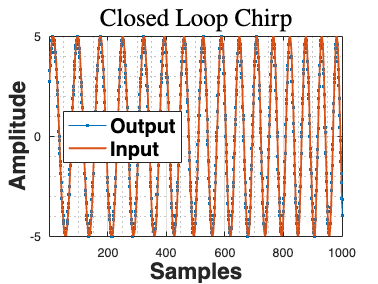

% Open and Closed loop Input Output Data Processesing
% Saves plots as PDFs
clear; 
clc; 
addpath("utils/")
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
%%%%%%%%%%%%%%% Preprocess Closed Loop DataSets
[~, cl_ramp_rps, cl_ramp_ref, cl_ramp_u] = extractMotorData("DataSets/cl_zn_ramp10.csv");
[timestamps, cl_step_rps, cl_step_ref, cl_step_u ] = extractMotorData("DataSets/cl_zn_step.csv");
[~, cl_chirp_rps, cl_chirp_ref, cl_chirp_u] = extractMotorData("DataSets/cl_zn_chrip8_1.csv");
%%%%%%%%%%% Closed loop Chirp
fig = figure;
graphInOutData(cl_chirp_rps(1301:2301), cl_chirp_ref(1301:2301), 'Closed_Loop_Chirp', folderpath, false);

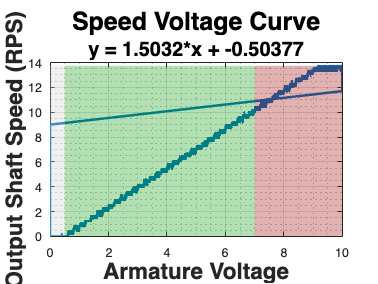

%%%%%%%%%%%%%%%%% Preprocess OpenLoop Datasets
[~, ramp_rps, ramp_volt, ~] = extractMotorData("DataSets/ramp10_100.csv");
[~, sin1_1_rps, sin1_1_volt, ~] = extractMotorData("DataSets/sin_1_1_100.csv");
[~, sin5_5_rps, sin5_volt, ~] = extractMotorData("DataSets/sin_5_5_100.csv");
[~, sin1_8_rps, sin1_8_volt, ~] = extractMotorData("DataSets/sin_1_8_100.csv");
[~, step_rps, step_volt, ~] = extractMotorData("DataSets/openStep.csv");
[~, trig_rps, trig_volt, ~] = extractMotorData("DataSets/openTrig.csv");
%%%%%%%%%%%% Speed-Voltage Curve 
fig = figure;
plot(ramp_volt, ramp_rps, 'LineWidth', 2); 
hold on
c = polyfit(ramp_volt, ramp_rps,1);
subtitle(['y = ' num2str(c(1)) '*x + ' num2str(c(2))], 'FontSize', 16, 'FontWeight', 'bold');
y_min = min(ramp_rps);
y_max = max(ramp_rps);
y_height = y_max - y_min;
% Nominal Operation Section
x_start = 0.5; 
x_width = 6.5;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.0 0.6 0 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% Overdrive Section
x_start = 7; 
x_width = max(ramp_volt) - x_start;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.6 0.0 0 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
% DeadZone Section
x_start = 0; x_width = 0.5;
rectangle('Position', [x_start, y_min, x_width, y_height], ...
          'FaceColor', [0.8 0.8 0.8 0.1], 'FaceAlpha', 0.3, 'EdgeColor', 'none');
grid on; grid minor; 
title("Speed Voltage Curve", 'FontSize', 20, 'FontWeight', 'bold'); 
ylabel("Output Shaft Speed (RPS)", 'FontSize', 18, 'FontWeight', 'bold'); 
xlabel("Armature Voltage", 'FontSize', 18, 'FontWeight', 'bold');
hold off;
exportgraphics(fig, fullfile(folderpath, "Speed_Voltage_Curve.pdf"));

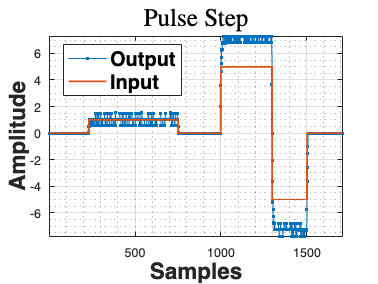

%%%%%%%%%%%%%%%%%%%%%% Plot Open Loop Data 
graphInOutData(step_rps(200:end), step_volt(200:end),'Pulse_Step', folderpath,false);

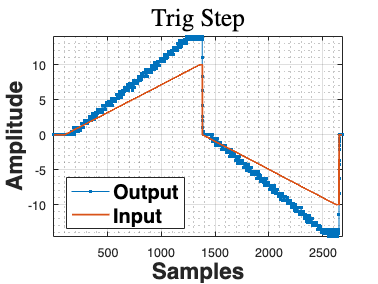

graphInOutData(trig_rps, trig_volt, 'Trig_Step', folderpath, false);

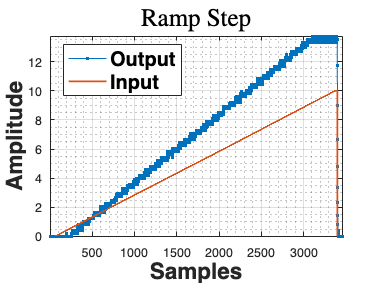

graphInOutData(ramp_rps, ramp_volt, 'Ramp_Step', folderpath, false);

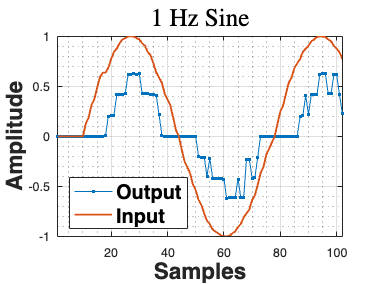

graphInOutData(sin1_1_rps(100:201), sin1_1_volt(100:201), '1_Hz_Sine', folderpath, false);

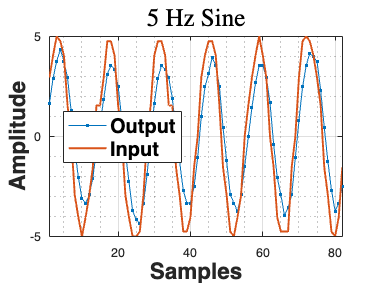

graphInOutData(sin5_5_rps(65:146), sin5_volt(65:146), '5_Hz_Sine', folderpath, false);

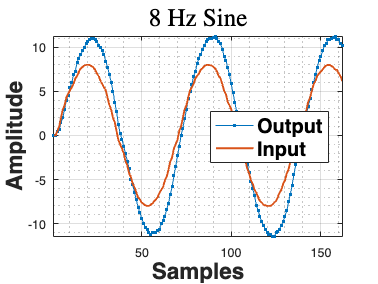

graphInOutData(sin1_8_rps(40:201), sin1_8_volt(40:201), '8_Hz_Sine', folderpath, false);

%%%%%%%%%%%%%%%%%%%%% Input-output plotting helper function
function graphInOutData(outputData, inputData, plotTitle, folderpath, log, legendNames)
    % Check if the legendNames is provided, otherwise default to "Output" and "Input"
    if nargin < 6
        legendNames = {"Output", "Input"};
    end

    % Replace underscores with spaces for the plot title (but not the filename)
    plotTitleFormatted = strrep(plotTitle, '_', ' ');

    % Create plot based on log flag
    if log
        fig = figure;
        semilogx(outputData, 'LineWidth', 2)
        hold on;
        semilogx(inputData, '-', 'LineWidth', 2);
        hold off;
    else
        fig = figure;
        plot(outputData, 'Marker', '.');
        hold on;
        plot(inputData, '-', 'LineWidth', 1.5);
        hold off;
    end
    grid on; grid minor;
    title(plotTitleFormatted, 'FontSize', 20, 'FontWeight', 'bold', 'Interpreter', 'latex'); 
    legend(legendNames, 'FontSize', 16, 'Location', 'best', 'FontWeight', 'bold');
    xlabel('Samples', 'FontSize', 18, 'FontWeight', 'bold');
    ylabel('Amplitude', 'FontSize', 18, 'FontWeight', 'bold');
    axis tight;
    
    % Export plot to pdf
    filepath = fullfile(folderpath, plotTitle + ".pdf");
    exportgraphics(fig, filepath);
end